% MECH 6318 - Homework 6
% Jonas Wagner
% 2021-10-06

close all
clear


## Problem 12.4

f = @(x) -3 .* x.^3 + 12*(x.^(-2)) + 2*exp(x.^2);
df = matlabFunction(diff(f(sym('x'))));
ddf = matlabFunction(diff(diff(f(sym('x')))));

f_x = f(sym('x'))

$$f\_x = 2\,{\mathrm{e}}^{x^{2}}+\frac{12}{x^{2}}-3\,x^{3}$$

df_x = df(sym('x'))

$$df\_x = 4\,x\,{\mathrm{e}}^{x^{2}}-9\,x^{2}-\frac{24}{x^{3}}$$

ddf_x = ddf(sym('x'))

$$ddf\_x = 4\,{\mathrm{e}}^{x^{2}}-18\,x+8\,x^{2}\,{\mathrm{e}}^{x^{2}}+\frac{72}{x^{4}}$$


x_min = 0.5;
x_max = 2;

## Part 1b: Newton-Raphson Method By Hand

p = @(x) df(x)/ddf(x);
p_x = p(sym('x'))

$$p\_x = -\frac{9\,x^{2}-4\,x\,{\mathrm{e}}^{x^{2}}+\frac{24}{x^{3}}}{4\,{\mathrm{e}}^{x^{2}}-18\,x+8\,x^{2}\,{\mathrm{e}}^{x^{2}}+\frac{72}{x^{4}}}$$


x_0 = 1

x_0 = 1

f_1 = f(x_0)

f_1 = 14.4366

df_1 = df(x_0)

df_1 = -22.1269

ddf_1 = ddf(x_0)

ddf_1 = 86.6194

p_1 = p(x_0)

p_1 = -0.2554

x_1 = x_0 - p_1

x_1 = 1.2554


f_2 = f(x_1)

f_2 = 11.3498

df_2 = df(x_1)

df_2 = -2.0271

ddf_2 = ddf(x_1)

ddf_2 = 86.7119

p_2 = p(x_1)

p_2 = -0.0234

x_2 = x_1 - p_2

x_2 = 1.2788


f_3 = f(x_2)

f_3 = 11.3265

df_3 = df(x_2)

df_3 = 0.0550

ddf_3 = ddf(x_2)

ddf_3 = 91.5640

p_3 = p(x_2)

p_3 = 6.0025e-04

x_3 = x_2 - p_3

x_3 = 1.2782


f_4 = f(x_3)

f_4 = 11.3265

df_4 = df(x_3)

df_4 = 4.0833e-05

## Part 1d: Plot f(x)

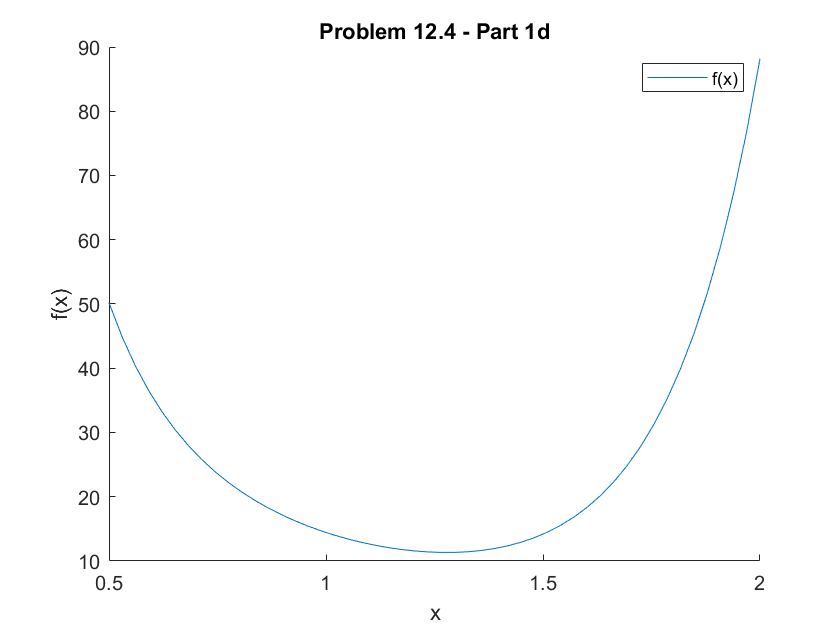

X_all = linspace(x_min,x_max,50);
F_all = f(X_all);
figure()
hold on
plot(X_all,F_all, 'DisplayName', 'f(x)')
% scatter([x_0,x_1,x_2,x_3],...
%         [f_1,f_2,f_3,f_4],...
%         'DisplayName', 'Newton-Raphson Method')
% hold off
legend()
xlabel('x')
ylabel('f(x)')
title('Problem 12.4 - Part 1d')

## Part 2: Newton-Raphson in MATLAB

disp('Part 2 - Coded Newto-Raphson -------------------------------------')

Part 2 - Coded Newto-Raphson -------------------------------------


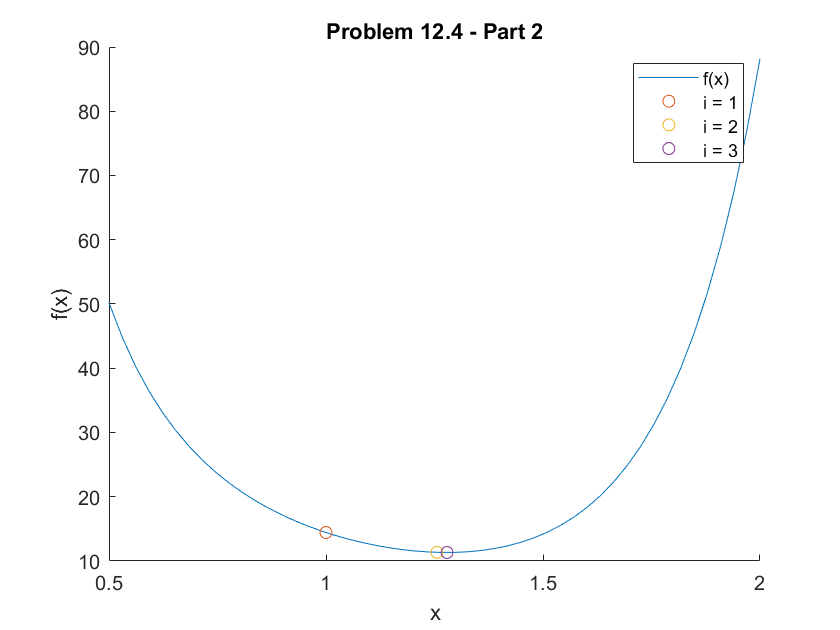

Number of iterations: 3


Optimal Variable: 1.2782


Optimal Value: 11.3265


figure()
hold on
plot(X_all,F_all, 'DisplayName', 'f(x)')
legend()
xlabel('x')
ylabel('f(x)')
title('Problem 12.4 - Part 2')

x_0 = 1;
epsilon = 0.01;
max_itr = 10;
X(1) = x_0;
for i = 1:max_itr
    F(i) = f(X(i));
    DF(i) = df(X(i));
    DDF(i) = ddf(X(i));
    P(i) = p(X(i));
    X(i+1) = X(i) - P(i);
    scatter([X(i)],[F(i)],'DisplayName',['i = ',num2str(i)])
    if (abs(df(X(i+1))) < epsilon)
        disp(['Number of iterations: ', num2str(i)])
        disp(['Optimal Variable: ', num2str(X(i+1))])
        disp(['Optimal Value: ', num2str(f(X(i+1)))])
        break
    end
end

## Part 3 : fmincon validation

disp('Part 3 - fmincon validation -------------------------------------')

Part 3 - fmincon validation -------------------------------------


[x_star, f_star, exitflag, output] = fmincon(f,x_0,[],[],[],[],x_min,x_max)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_star = 1.2782

f_star = 11.3265

exitflag = 1

output = struct with fields:
         iterations: 8
          funcCount: 19
    constrviolation: 0
           stepsize: 2.0168e-09
          algorithm: 'interior-point'
      firstorderopt: 2.7777e-07
       cgiterations: 0
            message: '↵Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.777746e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵'
       bestfeasible: [1×1 struct]


## Part 4: final notes

The cold I wrote goes through 3 iterations but fmincon goes through 8. fmincon is using the interior-point method, so more iterations makes sense.